% I'll start with simulating a data matrix.
rng(12)
n_timepoints = 5;
n_observations = 50;
data_matrix = zeros(n_observations, n_timepoints);
sigma2 = 1;
rho = 0;

for i=1:n_observations
    first_value = normrnd(0,sqrt(sigma2),1);
    data_matrix(i,1) = first_value;
    for j = 2:n_timepoints
        data_matrix(i,j) = rho*data_matrix(i,j-1) + normrnd(0,sqrt(sigma2),1);
    end
end

solve_this = @(a) (ar1_constraint(a));
options = optimoptions('fsolve','Display','None','TolFun', ...
        8e-6, 'MaxFunctionEvaluations', 3e5, 'MaxIterations', 3e5);
[U, Lambda2, ~] = svd(cov(data_matrix));
Lambda = diag(diag(Lambda2.^(0.5)));
original_sign = sign(det(U));
my_count = 0;
[d,~] = size(Lambda);
for i = 0:(2^d-1)
    temp_signs = de2bi(i,8);
    temp_signs = 2*temp_signs(1:d)-1;
    if(1==original_sign*prod(temp_signs))
        tempUhat = U*diag(temp_signs);
        tempA = (eye(d) - tempUhat)/(eye(d) + tempUhat);
        temp_vector = collapseParameters(tempA,Lambda);
%         initial = collapseParameters(actualA,Lambda);
        temp_vector = fsolve(solve_this, temp_vector, options);
        if( 1 == prod(temp_vector((d+1):end)>-1 & temp_vector((d+1):end)<1))
            disp("got here");
            [actualA,~] = uncollapseParameters(temp_vector);
            actualU = tempUhat;
            initial_guess = temp_vector
            break
        end
    end
end

solve_this = @(a) (ar1_constraint_justc(a));
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);
initial = collapseParameters(A,Lambda);
% initial = [-5, log(0.1), log(0.4), log(1.6), log(1.5), log(2.3), log(1.5), log(2.4), log(2.1),...
%     log(1.2), log(1.25), log(1.3), log(0.6), log(0.7),...
%     log(0.5), log(0.4), log(0.3), ...
%     -2.5];
% initial = [-2, log(1), log(2), log(1), log(0.9), log(0.7), log(0.4), -2];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =     0.5259
    0.5302
    0.5169
    0.5220
    0.5086
    0.8714
   -3.3759
    0.6036
   -1.2619
    0.2754



num_iters = 10000;
burn_in = 1;
proposal_scale = 1e-4

proposal_scale = 1.0000e-04


ll_function = @(x) ll_density(x, data_matrix);
constraintFunc = @(x) (ar1_constraint(x));
dConstraintFunc = @(x) (dar1_constraint(x));

warning('off');


nRuns = 1+10;
Nscale = 700;
runTime = 15; % Time per run in seconds
nTrials = 100;
doPrint = false;

samplers = struct([]);

h = 1e-4;
M = 1;
L = 2;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end
mean(samplerStats{1,1}.accepted)
Qs = samplerQs{1,1};
save("MH_logsplineDraws_other.mat",'Qs');

MH ratio is: 6.873790e+00.
MH ratio is: 6.404309e+00.
MH ratio is: 2.537186e+01.
MH ratio is: -1.310600e+01.
MH ratio is: 1.531356e+01.
MH ratio is: -1.654019e+03.
MH ratio is: 1.003707e+01.
MH ratio is: 8.525013e-02.
MH ratio is: -7.020877e-01.
MH ratio is: -1.249125e+01.
MH ratio is: -7.884407e+00.
MH ratio is: -1.196772e+01.
MH ratio is: -9.673118e+00.
MH ratio is: -1.741259e+02.
MH ratio is: -5.446165e+00.
MH ratio is: -6.709661e+01.
MH ratio is: -2.095338e+08.
MH ratio is: -9.649855e+00.
MH ratio is: -7.450247e+00.
MH ratio is: -8.641657e+01.
MH ratio is: -1.717818e-03.
MH ratio is: -3.258980e+00.
MH ratio is: -4.860984e+02.
MH ratio is: -4.829157e-01.
MH ratio is: -8.746255e-02.
MH ratio is: -5.970327e+00.
MH ratio is: -4.134639e-01.
MH ratio is: -3.063285e-02.
MH ratio is: -1.148405e+00.
MH ratio is: -2.676474e+08.
MH ratio is: -5.596039e+00.
MH ratio is: -1.475284e+01.
MH ratio is: -6.264336e+00.
MH ratio is: -1.519291e+00.
MH ratio is: -2.318115e+00.
MH ratio is: -7.993906e-01

ans = 0.1300

## Use the samples to calculate values for rho and sigma2:

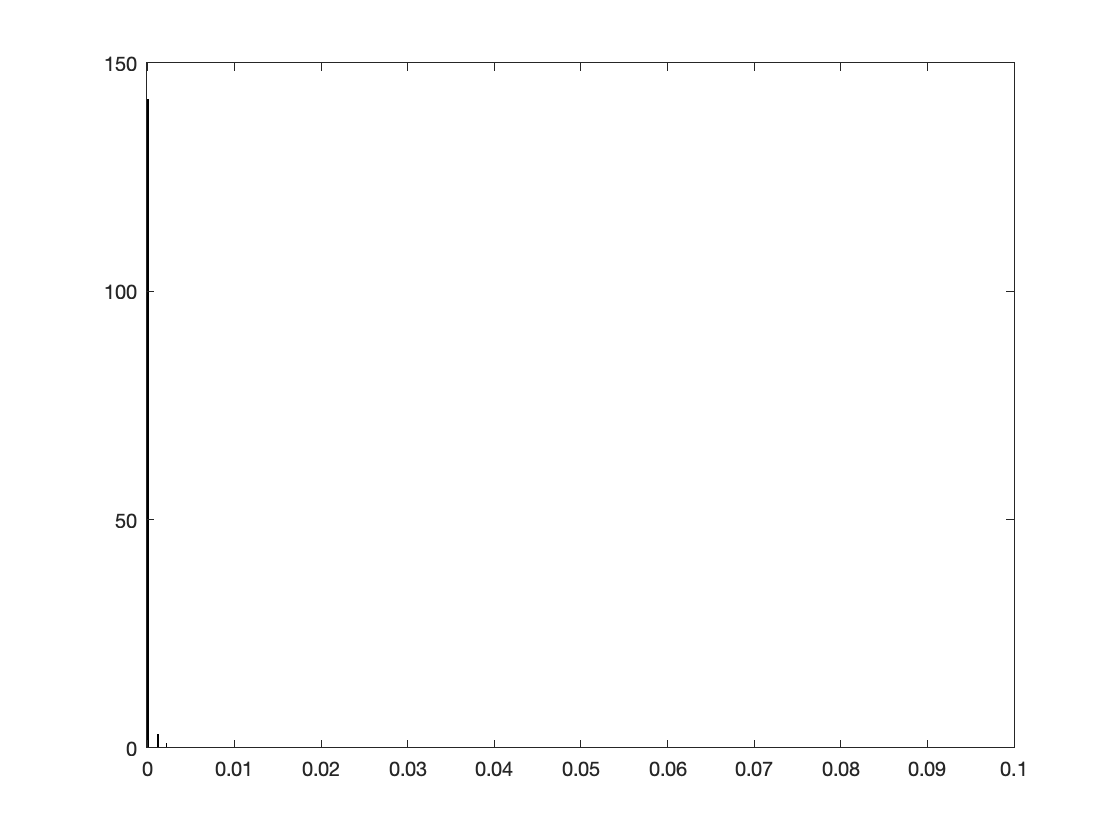

samples = load("HMC_ar1_Draws.mat").samples;
[~,num_of_samples] = size(samples);
rhos = zeros(1,num_of_samples);
s2s = zeros(1,num_of_samples); 

for i=1:num_of_samples
    [A, Lambda] = uncollapseParameters(samples(:,i));
    U = (eye(n_timepoints) - A)/(eye(n_timepoints) + A);
    sigma = U*(Lambda.^2)*(U');
    rhos(i) = sigma(1,2)/sigma(1,1);
    s2s(i) = sigma(1,1)/(1 - (sigma(1,2)/sigma(1,1)).^2);
end

histogram(rhos);
hold on
xline(rho);
hold off

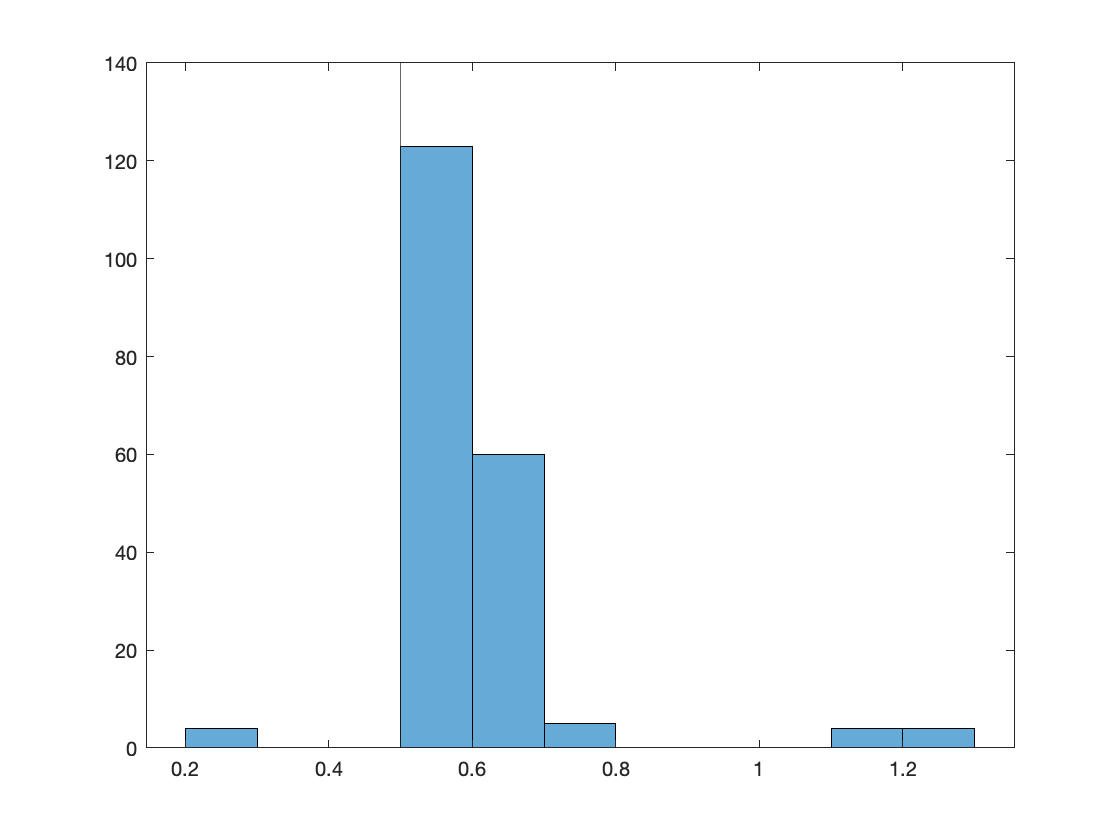


histogram(s2s);
hold on
xline(sigma2);
hold off